% Define the serial port and baud rate
arduinoPort = "COM9"; % Replace with the correct COM port for your Arduino
baudRate = 115200;      % Must match the Arduino sketch

% Create the serial port object
arduino = serialport(arduinoPort, baudRate);

% Set the number of bytes to read (optional)
configureTerminator(arduino, "CR/LF"); % Match the newline terminator used in Arduino

% Initialize arrays with fixed lengths
numPoints = 100;
time_arr = zeros(1, numPoints);
pressure_arr = zeros(1, numPoints);
altitude_arr = zeros(1, numPoints);

% Initialize figure and subplots
figure
subplot(2,1,1)
h1 = plot(0,0); % Create empty plot handle
title('Pressue (Pa)')
grid on

subplot(2,1,2)
h2 = plot(0,0); % Create empty plot handle
title('Altitude (m)')
grid on

% Read and display data
disp('Reading data from Arduino...');

Reading data from Arduino...


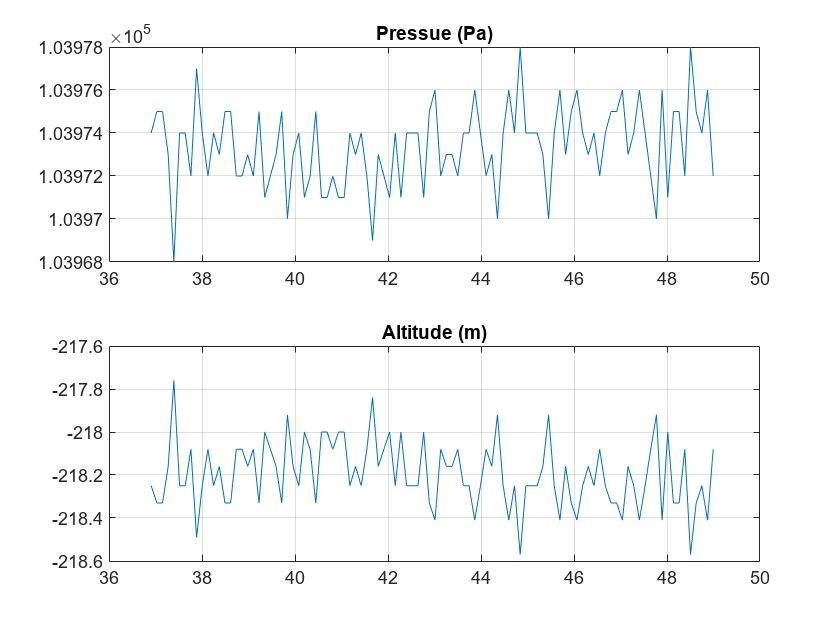

while true
    % Read one line of data
    data = readline(arduino);
    data_arr = split(data, ',');
   
    try
        time = str2double(data_arr(1)) * 10^-6; % ms to s
        pressure = data_arr(2);
        altitude = data_arr(3);
    
        % Update arrays by shifting and adding new values
        time_arr = [time_arr(2:end), time];
        pressure_arr = [pressure_arr(2:end), str2double(pressure)];
        altitude_arr = [altitude_arr(2:end), str2double(altitude)];
        disp(stf(altitude_arr));
    end
    
    % Time to plot
    set(h1, 'YData', pressure_arr, 'XData', time_arr);
    set(h2, 'YData', altitude_arr, 'XData', time_arr);
    
    drawnow
end